# Exercise 4

clc;
close all;
clear variables;

set(groot, 'defaulttextinterpreter', 'latex');  
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');  
set(groot, 'defaultLegendInterpreter', 'latex');

## Roll-Pitch-Yaw

Rx = @(t) [1, 0, 0;
           0, cos(t), -sin(t);
           0, sin(t),  cos(t)];

Ry = @(t) [cos(t), 0, sin(t);
           0, 1, 0;
          -sin(t), 0, cos(t)];

Rz = @(t) [cos(t), -sin(t), 0;
           sin(t),  cos(t), 0;
           0, 0, 1];

RPY = @(alpha, beta, gamma) Rz(alpha) * Ry(beta) * Rx(gamma);

syms alpha beta gamma

simplify(RPY(alpha, beta, gamma))

$$ans = \left(\begin{array}{ccc} \cos\left(\alpha \right)\,\cos\left(\beta \right) & \cos\left(\alpha \right)\,\sin\left(\beta \right)\,\sin\left(\gamma \right)-\cos\left(\gamma \right)\,\sin\left(\alpha \right) & \sin\left(\alpha \right)\,\sin\left(\gamma \right)+\cos\left(\alpha \right)\,\cos\left(\gamma \right)\,\sin\left(\beta \right)\\ \cos\left(\beta \right)\,\sin\left(\alpha \right) & \cos\left(\alpha \right)\,\cos\left(\gamma \right)+\sin\left(\alpha \right)\,\sin\left(\beta \right)\,\sin\left(\gamma \right) & \cos\left(\gamma \right)\,\sin\left(\alpha \right)\,\sin\left(\beta \right)-\cos\left(\alpha \right)\,\sin\left(\gamma \right)\\ -\sin\left(\beta \right) & \cos\left(\beta \right)\,\sin\left(\gamma \right) & \cos\left(\beta \right)\,\cos\left(\gamma \right) \end{array}\right)$$

## Task 1

R = RPY(deg2rad(90), deg2rad(90), 0)

R =     0.0000   -1.0000    0.0000
    0.0000    0.0000    1.0000
   -1.0000         0    0.0000


theta = atan2(sqrt((R(3, 2) - R(2, 3))^2 + ...
                   (R(1, 3) - R(3, 1))^2 + ...
                   (R(2, 1) - R(1, 2))^2), ...
                    R(1,1) + R(2, 2) + R(3, 3) - 1)

theta = 2.0944

k = [sign(R(3, 2) - R(2, 3)) * sqrt((R(1, 1) - cos(theta)) / (1 - cos(theta)));
     sign(R(1, 3) - R(3, 1)) * sqrt((R(2, 2) - cos(theta)) / (1 - cos(theta)));
     sign(R(2, 1) - R(1, 2)) * sqrt((R(3, 3) - cos(theta)) / (1 - cos(theta)))]

k =    -0.5774
    0.5774
    0.5774


k = k / norm(k)

k =    -0.5774
    0.5774
    0.5774


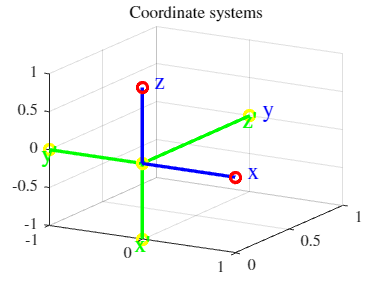

I = eye(3);
txt = {'x', 'y', 'z'};
txt_ = {"x'", "y'", "z'"};

delta = 0.05;

figure
hold on
grid on
view([30, 20])
for i = 1:3
    plot3([0, I(i, 1)], [0, I(i, 2)], [0, I(i, 3)], 'b', 'LineWidth', 2)
    plot3([0, I(i, 1)], [0, I(i, 2)], [0, I(i, 3)], 'ro', 'LineWidth', 2)

    plot3([0, R(1, i)], [0, R(2, i)], [0, R(3, i)], 'g', 'LineWidth', 2)
    plot3([0, R(1, i)], [0, R(2, i)], [0, R(3, i)], 'yo', 'LineWidth', 2)

    text(I(i, 1) + delta, I(i, 2) + delta, I(i, 3) + delta, txt{i}, 'FontSize', 14, 'Color','b')
    text(R(1, i) - delta, R(2, i) - delta, R(3, i) - delta, txt_{i}, 'FontSize', 14, 'Color','g')

end
title('Coordinate systems')

## Task 2

clear k theta
k = [0; 1; 0];
theta = 90;

vers = @(t) 1 - cos(t);
Rk = @(k, theta) [k(1) * k(1) * vers(theta) + cos(theta), k(2) * k(1) * vers(theta) - k(3) * sin(theta), k(3) * k(1) * vers(theta) + k(2) * sin(theta);
                  k(2) * k(1) * vers(theta) + k(3) * sin(theta), k(2) * k(2) * vers(theta) + cos(theta), k(3) * k(2) * vers(theta) - k(1) * sin(theta);
                  k(3) * k(1) * vers(theta) - k(2) * sin(theta), k(3) * k(2) * vers(theta) + k(1) * sin(theta), k(3) * k(3) * vers(theta) + cos(theta)];

rk = round(Rk(k, deg2rad(theta)))

rk =      0     0     1
     0     1     0
    -1     0     0


eq = rk == RPY(alpha, beta, gamma)

$$eq = \left(\begin{array}{ccc} 0=\cos\left(\alpha \right)\,\cos\left(\beta \right) & 0=\cos\left(\alpha \right)\,\sin\left(\beta \right)\,\sin\left(\gamma \right)-\cos\left(\gamma \right)\,\sin\left(\alpha \right) & 1=\sin\left(\alpha \right)\,\sin\left(\gamma \right)+\cos\left(\alpha \right)\,\cos\left(\gamma \right)\,\sin\left(\beta \right)\\ 0=\cos\left(\beta \right)\,\sin\left(\alpha \right) & 1=\cos\left(\alpha \right)\,\cos\left(\gamma \right)+\sin\left(\alpha \right)\,\sin\left(\beta \right)\,\sin\left(\gamma \right) & 0=\cos\left(\gamma \right)\,\sin\left(\alpha \right)\,\sin\left(\beta \right)-\cos\left(\alpha \right)\,\sin\left(\gamma \right)\\ -1=-\sin\left(\beta \right) & 0=\cos\left(\beta \right)\,\sin\left(\gamma \right) & 0=\cos\left(\beta \right)\,\cos\left(\gamma \right) \end{array}\right)$$

sol = solve(eq)

sol = struct with fields:
    alpha: [4×1 sym]
     beta: [4×1 sym]
    gamma: [4×1 sym]


sol.alpha

$$ans = \left(\begin{array}{c} 0\\ -\frac{\pi }{2}\\ \frac{\pi }{2}\\ \pi \end{array}\right)$$

sol.beta

$$ans = \left(\begin{array}{c} \frac{\pi }{2}\\ \frac{\pi }{2}\\ \frac{\pi }{2}\\ \frac{\pi }{2} \end{array}\right)$$

sol.gamma

$$ans = \left(\begin{array}{c} 0\\ -\frac{\pi }{2}\\ \frac{\pi }{2}\\ \pi \end{array}\right)$$

## Task 3

### a)

syms d_alpha d_beta d_gamma
Ri = RPY(alpha, beta, gamma);
Rd = RPY(d_alpha, d_beta, d_gamma);
R_plus = RPY(alpha + d_alpha, beta + d_beta, gamma + d_gamma);
R_product = Rd * Ri; 

R_plus(3, 1)

$$ans = -\sin\left(\beta +d_{\beta }\right)$$

R_product(3, 1)

$$ans = \cos\left(\beta \right)\,\cos\left(d_{\beta }\right)\,\sin\left(\alpha \right)\,\sin\left(d_{\gamma }\right)-\cos\left(d_{\beta }\right)\,\cos\left(d_{\gamma }\right)\,\sin\left(\beta \right)-\cos\left(\alpha \right)\,\cos\left(\beta \right)\,\sin\left(d_{\beta }\right)$$

isequal(R_plus(3, 1), R_product(3, 1))

ans = logical
   0


### b)

angles_0 = [-90; 90; 0];
angles_n = [0; 0; 0];

n = 2;
d_angles = (angles_n - angles_0) / n;
r_plus = subs(R_plus(3, 1), [beta, d_beta], [angles_0(2), d_angles(2)])

$$r\_plus = -\sin\left(45\right)$$

r_product = eval(simplify(subs(R_product(3, 1), [alpha, beta, gamma, d_alpha, d_beta, d_gamma], [angles_0', d_angles'])))

r_product = -0.2988

This doesn't match up with the solution!

## Task 4

syms phi

quat = @(theta, n) [cos(theta/2); sin(theta/2) * n];

### a)

q = quat(phi, [1; 0; 0])

$$q = \left(\begin{array}{c} \cos\left(\frac{\varphi }{2}\right)\\ \sin\left(\frac{\varphi }{2}\right)\\ 0\\ 0 \end{array}\right)$$

Rq = @(q) [1 - 2 * (q(3)^2 + q(4)^2), 2 * (q(2) * q(3) - q(1) * q(4)), 2 * (q(2) * q(4) + q(1) * q(3));
           2 * (q(2) * q(3) + q(1) * q(4)), 1 - 2 * (q(2)^2 + q(4)^2), 2 * (q(3) * q(4) - q(1) * q(2));
           2 * (q(2) * q(4) - q(1) * q(3)), 2 * (q(3) * q(4) + q(1) * q(2)), 1 - 2 * (q(2)^2 + q(3)^2)];

simplify(Rq(q))

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\varphi \right) & -\sin\left(\varphi \right)\\ 0 & \sin\left(\varphi \right) & \cos\left(\varphi \right) \end{array}\right)$$

### b)

n = [1;2;3];
q = simplify(quat(phi, n / norm(n)))

$$q = \left(\begin{array}{c} \cos\left(\frac{\varphi }{2}\right)\\ \frac{\sqrt{14}\,\sin\left(\frac{\varphi }{2}\right)}{14}\\ \frac{\sqrt{14}\,\sin\left(\frac{\varphi }{2}\right)}{7}\\ \frac{3\,\sqrt{14}\,\sin\left(\frac{\varphi }{2}\right)}{14} \end{array}\right)$$

### c)

v = [1; 1; 1];
qrot = eval(subs(q, phi, deg2rad(45)))

qrot =     0.9239
    0.1023
    0.2046
    0.3068


Qrot = quaternion(qrot')

Qrot = quaternion
     0.92388 + 0.10228i + 0.20455j + 0.30683k


v_ = rotatepoint(Qrot, v')

v_ =     0.6437    1.3361    0.8947
